load('C:\Users\mrsco\Box\DataAndAnalysis\labData\OKR\batch\cellList_OKR2P.mat')

%choose which protocols to look at
priorityOrder_1 = {'OscillatingGrating'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ID1101'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ID1101'};
cantHave_1 = [];
cantHave_2 = {}; %avoid anything with these tags
rigMandates = []; %no rig mandates

isUp = [];
xCoords = [];
yCoords = [];
upPSTHs = [];
downPSTHs = [];
obj = analysisSuperClass;
for i = 1:size(cellList, 1)
    struct_i = cellList{i, 2};
    %ask whether the current cell has the requested analysis
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);    
    if pass
        continue
    end
     if contains(struct_i.cellID, 'SHOKR119L') %this animal only had one cell type labeled, so excluding
         continue
     end
    polCoords = -struct_i.coordinates.polar;
    [cartX, cartY] = pol2cart(polCoords(1), polCoords(2));
    xCoords(end + 1) = -cartX;
    yCoords(end + 1) = cartY;
    
    allSpikeTimes = loc.Analysis_Results.allSpikeTimes;
    
    period = loc.Analysis_Results.motionPeriod; %seconds
    period_ms = period*1000; %ms
    numCycles = loc.Analysis_Results.numCyclesPerEpoch;
    stimLength = period_ms*numCycles; %ms
    cycleStartTimes = 0:period_ms:stimLength-period_ms; %ms - time at which the oscillation cycle restarts
    phaseShift = loc.Analysis_Results.motionPhaseShift;
    
    binWidth = 40; %ms
    numBins = stimLength/binWidth;
    allPSTH = zeros(size(allSpikeTimes, 2), numBins);
    for j = 1:size(allSpikeTimes, 2)
        spikes_j = allSpikeTimes(j); %cell array
        allPSTH(j, :) = obj.buildPSTH(spikes_j, binWidth, 0, stimLength)./(binWidth*1e-3); %hz
    end
    meanPSTH = mean(allPSTH, 1);
    smoothedPSTH = movmean(meanPSTH, 12);
    
    %recreate the position of the stimulus
    periodTerm = 2*pi/period;
    shiftTerm = deg2rad(phaseShift);
    %calculates stimulus position ON THE RETINA (not in visual coordinates)
    stimulusPositionFunc = @(time, shift) cos(periodTerm*time + shift)/periodTerm;
    
    binsPerCycle = period_ms/binWidth;
    binStart = 1; binEnd = binsPerCycle;
    singleCyclePSTH = zeros(numCycles, binsPerCycle);
    for j = 1:numCycles
        singleCyclePSTH(j, :) = smoothedPSTH(binStart:binEnd);
        binStart = binStart + binsPerCycle;
        binEnd = binEnd + binsPerCycle;
    end
    meanSingleCyclePSTH = mean(singleCyclePSTH, 1);

    %adjust for the motion phase shift if necessary
    phaseShiftBins = round(mod(phaseShift, 360)*binsPerCycle/360);
    if phaseShiftBins ~= 0
        newStartBin = numel(meanSingleCyclePSTH)-phaseShiftBins;
        meanSingleCyclePSTH = [meanSingleCyclePSTH(newStartBin:end)...
            meanSingleCyclePSTH(1:newStartBin -1)];
    end
    
    tags = struct_i.Tags;
    if ismember('UP Cell', tags)
        upPSTHs(end + 1, :) = meanSingleCyclePSTH;
        isUp(end+1) = 1;
    elseif ismember('DOWN Cell', tags)
        downPSTHs(end + 1, :) = meanSingleCyclePSTH;
        isUp(end + 1) = 0;
    end
    
end
isUp = logical(isUp);
xvals = linspace(0, period, binsPerCycle);
stimulusPositionSingleCycle = stimulusPositionFunc(xvals, 0);

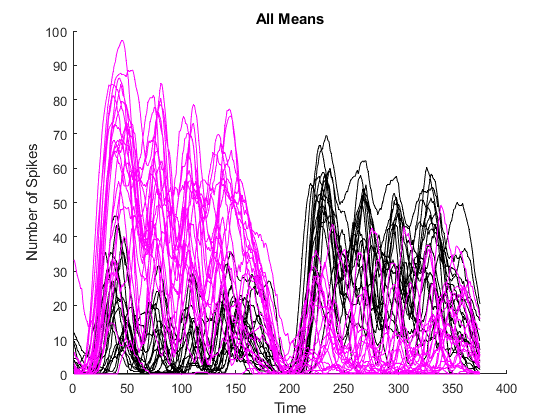

figure
title('All Means')
hold on
plot(upPSTHs', 'k')
plot(downPSTHs', 'm')
xlabel('Time')
ylabel('Number of Spikes')

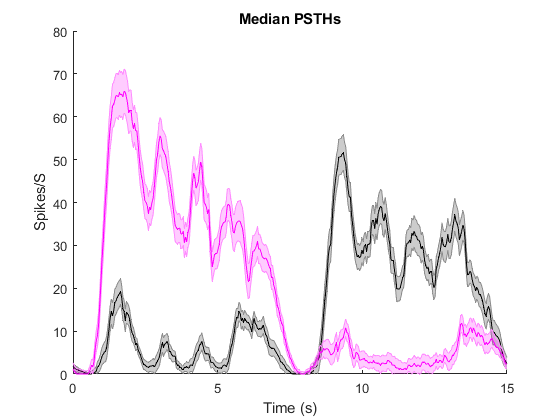

SE_F = @(m) std(m)/sqrt(size(m, 1));
figure;
title('Median PSTHs')
hold on
shadedErrorBar(xvals, median(upPSTHs), SE_F(upPSTHs), 'LineProps', {'Color', [0, 0, 0]})
shadedErrorBar(xvals, median(downPSTHs), SE_F(downPSTHs), 'LineProps', {'Color', [1, 0, 1]})
xlabel('Time (s)')
ylabel('Spikes/S')
ylim([0 80])

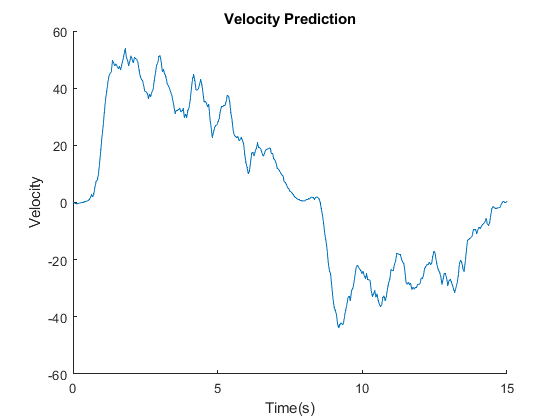


velocityLinearPrediction = median(downPSTHs) - median(upPSTHs);
velocityLinearPrediction = velocityLinearPrediction - velocityLinearPrediction(1);
positionLinearPrediction = cumtrapz(velocityLinearPrediction);

figure
title('Velocity Prediction')
hold on
plot(xvals, velocityLinearPrediction)
xlabel('Time(s)')
ylabel('Velocity')
ylim([-60 60])

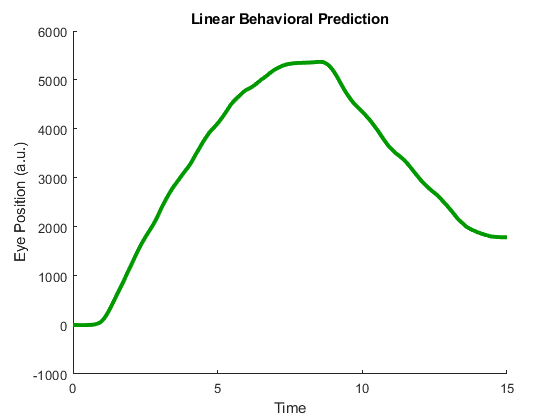


figure
title('Linear Behavioral Prediction')
hold on
plot(xvals, positionLinearPrediction, 'Color', [0, 0.6, 0], 'LineWidth', 3)
%plot(xvals, fL, 'k', 'LineWidth', 3)
xlabel('Time')
ylabel('Eye Position (a.u.)')

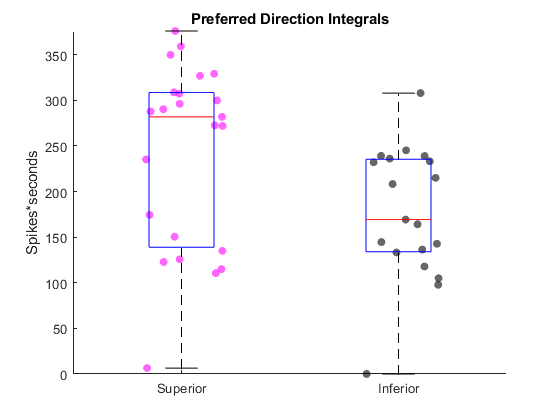

numBins = size(upPSTHs, 2);
timeLength = 15; %s
halfwayPoint = round(numBins/2);
upNDIntegral = trapz(upPSTHs(:, 1:halfwayPoint), 2)*timeLength/numBins;
upPDIntegral = trapz(upPSTHs(:, halfwayPoint+1:end), 2)*timeLength/numBins;
downPDIntegral = trapz(downPSTHs(:, 1:halfwayPoint), 2)*timeLength/numBins;
downNDIntegral = trapz(downPSTHs(:, halfwayPoint+1:end), 2)*timeLength/numBins;

allVals = [downPDIntegral; upPDIntegral]';
boxPlotGroups = zeros(1, numel(allVals));
boxPlotGroups(numel(downPDIntegral)+1:end) = 1;

figure
title('Preferred Direction Integrals')
hold on
scatter(zeros(1, numel(downPDIntegral))+1, downPDIntegral, 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upPDIntegral))+2, upPDIntegral, 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
boxplot(allVals, boxPlotGroups)
ylabel('Spikes*seconds')
ylim([0 inf])
box off
xticklabels({'Superior', 'Inferior'})

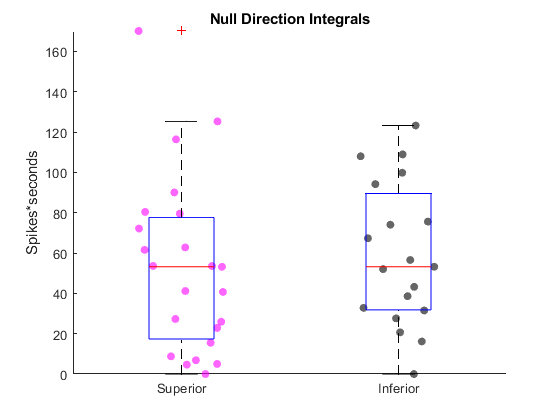

allVals = [downNDIntegral; upNDIntegral]';
boxPlotGroups = zeros(1, numel(allVals));
boxPlotGroups(numel(downNDIntegral)+1:end) = 1;

figure
title('Null Direction Integrals')
hold on
scatter(zeros(1, numel(downNDIntegral))+1, downNDIntegral, 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upNDIntegral))+2, upNDIntegral, 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
boxplot(allVals, boxPlotGroups)
ylabel('Spikes*seconds')
ylim([0 inf])
box off
xticklabels({'Superior', 'Inferior'})

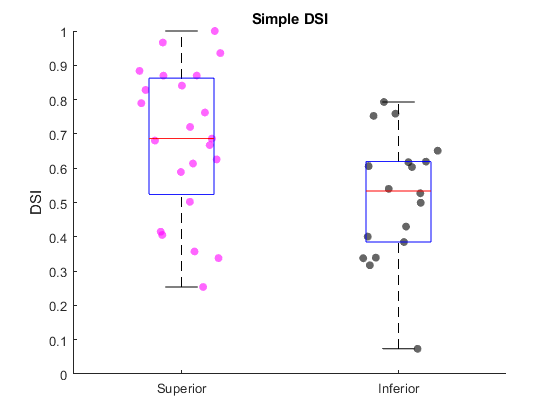

DSIMetric = @(v1, v2) (v1-v2)./(v1+v2);
allVals = [DSIMetric(downPDIntegral, downNDIntegral); DSIMetric(upPDIntegral, upNDIntegral)]';
boxPlotGroups = zeros(1, numel(allVals));
boxPlotGroups(numel(downNDIntegral)+1:end) = 1;

figure
title('Simple DSI')
hold on
scatter(zeros(1, numel(downNDIntegral))+1, DSIMetric(downPDIntegral, downNDIntegral), 'm', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
scatter(zeros(1, numel(upNDIntegral))+2, DSIMetric(upPDIntegral, upNDIntegral), 'k', 'filled', 'MarkerFaceAlpha', 0.6, 'jitter', 'on')
boxplot(allVals, boxPlotGroups)
ylabel('DSI')
ylim([0 inf])
box off
xticklabels({'Superior', 'Inferior'})

## Topography

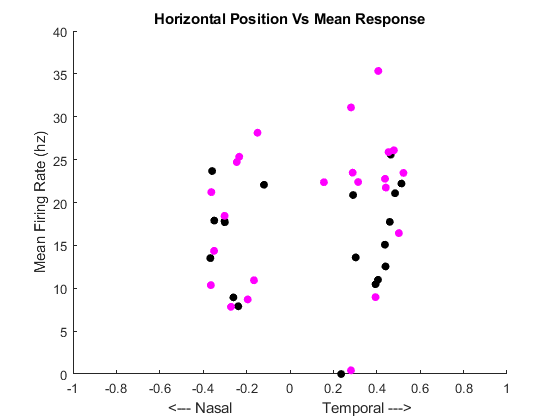

figure
title('Horizontal Position Vs Mean Response')
hold on
scatter(xCoords(isUp), mean(upPSTHs, 2), 'k', 'filled')
scatter(xCoords(~isUp), mean(downPSTHs,2), 'm', 'filled')
xlim([-1 1])
xlabel('<--- Nasal                      Temporal --->')
ylabel('Mean Firing Rate (hz)')

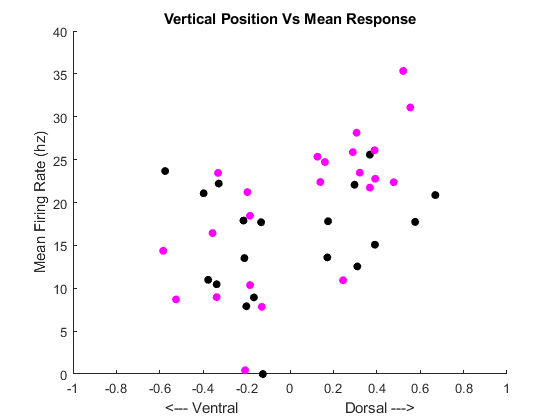

figure
title('Vertical Position Vs Mean Response')
hold on
scatter(yCoords(isUp), mean(upPSTHs, 2), 'k', 'filled')
scatter(yCoords(~isUp), mean(downPSTHs,2), 'm', 'filled')
xlim([-1 1])
xlabel('<--- Ventral                          Dorsal --->')
ylabel('Mean Firing Rate (hz)')

## Nonlinearity estimate

averageOscillation; %run the behavior script

p = 3.6255e-14

p = 0.0054

p = 0.0011

medianHighC = 3.1904

medianLowC = 0.6078

p = 2.0356e-10

p = 3.6255e-14

p = 0.0054

p = 7.1411e-29

m = 0.2755

p = 9.6581e-23

m = 0.1574

p = 7.1209e-10

ans = 0.1595

ans = 0.0304

p = 2.0356e-10

b =     0.2591    0.2485
    0.1658    0.1685


highC_behavior = mean(HighC_allEyeTraces);
close all
clc
behaviorVelocity = diff(highC_behavior)*numel(highC_behavior)/15; %deg/s (each oscillation is 15 seconds)

queries = linspace(1, numel(velocityLinearPrediction), numel(behaviorVelocity));
velocityLinearPredictionInterped = interp1([1:numel(velocityLinearPrediction)], velocityLinearPrediction, queries);

infVelocityIndices = behaviorVelocity < 0;
supVelocityIndices = behaviorVelocity >= 0;

infPredictedVelocities = velocityLinearPredictionInterped(infVelocityIndices);
infBehaviorVelocities = behaviorVelocity(infVelocityIndices);

supPredictedVelocities = velocityLinearPredictionInterped(supVelocityIndices);
supBehaviorVelocities = behaviorVelocity(supVelocityIndices);

figure
scatter(infPredictedVelocities, infBehaviorVelocities, 'k', 'filled', 'MarkerFaceAlpha', 0.6);
hold on
scatter(supPredictedVelocities, supBehaviorVelocities, 'm', 'filled', 'MarkerFaceAlpha', 0.6);
title('Empirical Nonlinearity')
xlabel('Sup-Inf FR (Hz)')
ylabel('Eye Velocity')

[R, P] = corr([infPredictedVelocities, supPredictedVelocities]', [infBehaviorVelocities, supBehaviorVelocities]', 'type', 'pearson')

R = 0.9241

P = 0


combinedPredictions = [infPredictedVelocities, supPredictedVelocities];
combinedBehaviors = [infBehaviorVelocities, supBehaviorVelocities];
numBins = 10;
[binIndices, binEdges] = discretize([infPredictedVelocities, supPredictedVelocities], numBins);
binMeans = zeros(1, numBins);
negativeErrors = zeros(1, numBins);
positiveErrors = zeros(1, numBins);
binCenters = zeros(1, numBins);
for i = 1:numBins
    indices_i = binIndices == i;
    binMeans(i) = median(combinedBehaviors(indices_i));
    [~, ~, negE, posE] = medianCI95Bootstrap(combinedBehaviors(indices_i), 10000);
    negativeErrors(i) = negE;
    positiveErrors(i) = posE;
    binCenters(i) = mean([binEdges(i), binEdges(i+1)]);
end
%scatter(binCenters, binMeans, 'filled', 'g')

%estimate sigmoid fit
params = sigm_fit(combinedPredictions, combinedBehaviors, [], [-2, 2, 0, 0.04], 0)

params =    -1.5981    2.0937    4.4164    0.0422


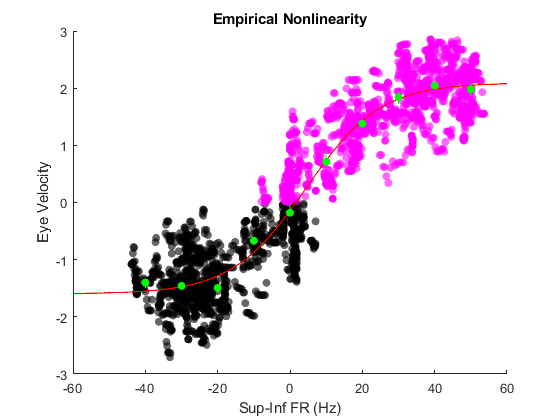

fsigm = @(params,xval) params(1)+(params(2)-params(1))./(1+10.^((params(3)-xval)*params(4)));
xQueries = [-60:0.1:60];
yFit = fsigm(params, xQueries);
plot(xQueries, yFit, '-r')
for i = 1:numBins
    scatter(binCenters(i), binMeans(i), 'g', 'filled')
    plot([binCenters(i), binCenters(i)], [-negativeErrors(i), positiveErrors(i)]+binMeans(i), 'g')
end

xlim([-60 60])
ylim([-3 3])